# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Explore and Organize Image Dataset 

Your goal in this step is to define defect classes and labels (keep it small).

- Load and inspect the images and labels from your chosen dataset (see the project page on GitHub for recommended datasets) to understand the part types, defect classes, and data balance

- Store labels in a table loaded by `readtable(...)`

- Manage images and labels with `imageDatastore(...)` and the `Labels` property (or use the example workflow for setting up labeled image datastores).

- Helpful reference: [Create and Explore Datastore for Image Classification](https://www.mathworks.com/help/deeplearning/ug/create-and-explore-datastore-for-image-classification.html).

- Choose 2-3 defect types (for FAIL) plus PASS

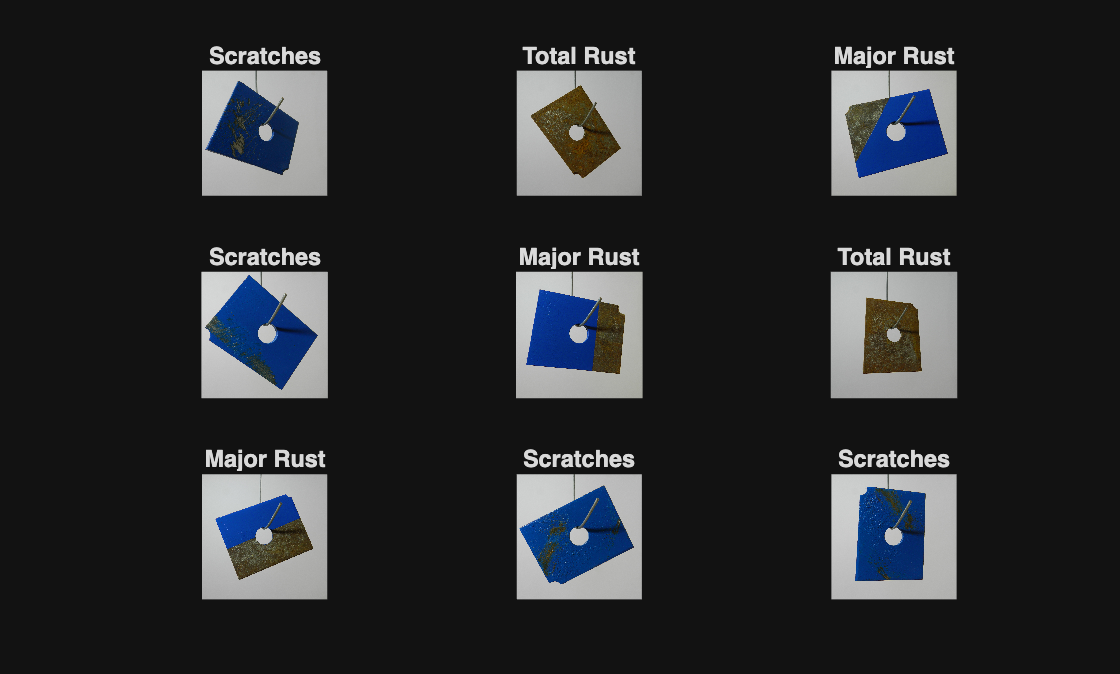

% Load dataset into partImgsds
% NOTE: Dataset folder must be in same folder as .mlx file (shouldn't be an
% issue if repository was cloned properly)
filepath = fileparts(matlab.desktop.editor.getActiveFilename);
dataFolder = fullfile(filepath, "Dataset"); 
partImgds = imageDatastore(dataFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

% Store total number of images
numImg = length(partImgds.Labels);
% Display a random sample of images for inspection & to confirm dataset was
% properly loaded
idx = randperm(numImg,9);
for i = 1:9
    subplot(3,3,i)
    imshow(readimage(partImgds,idx(i)))
    title(string(partImgds.Labels(idx(i))))
end

## Task 2: Build a Single-Image Inspection Function

Your goal in this step is to create a function that analyzes and image to identify and quantify suspected defects detected in the image. You're trying to answer the question: "What in the image looks suspicious?"

To build this function you will need to:

**STEP 1. Standardize the images**

- Read images with `imread(...)` or through `imageDatastore(...)`.

- Standardize size with `imresize(...)` so metrics and model input are consistent.

- Convert to grayscale with `rgb2gray(...)` as needed (e.g. classical processing may rely on intensity values)

**STEP 2. Preprocess the images**

- Apply classical preprocessing, prioritizing stability over complexity. In other words, apply only what you need to reduce sensitivity to normal station variation. Suggested processing includes:

- Lighting correction: `imflatfield(...)` (or background estimate with `imgaussfilt(...)` and subtraction)

- Contrast normalization: `adapthisteq(...)`

- Denoising: `medfilt2(...)` or `imgaussfilt(...)`

- Save intermediate results during development (e.g., `imshowpair(...)`) for quick debugging.

**STEP 3. *****Optionally*****, define a region of interest (ROI)**

If each image already contains a centered part with minimal clutter, skip ROI and use the full image:

- `roi = I;`

If needed, define ROI fully automatically (no per-image manual selection), by using, for example:

- Fixed crop defined once (camera is consistent): indexing or `imcrop(...) `OR

- Auto-crop from the part mask: segment the part, compute `BoundingBox` using `regionprops(...)`, then `imcrop(...)`.

**STEP 4. Segment the image for an evidence overlay**

Your goal is to generate an evidence overlay and a few measurable numbers—not a perfect segmentation. Generate a simple binary mask that highlights suspicious regions in the image. Use a defect-appropriate recipe and keep it short:

- Start with thresholding: `imbinarize(...)` or `adaptthresh(...)` + `imbinarize(...)`

- Clean small specks: `bwareaopen(...)`

- Bridge gaps (if appropriate): `imclose(...)`

- Fill holes (only when it matches your goal (e.g., for a clean outer part silhouette): `imfill(...,'holes')`

Deliverable: `maskEvidence = defectEvidence(roi)`

**STEP 5. Extract a small set of interpretable metrics**

Your goal is to quantify the evidence for suspected defects, which supports traceability and debugging in your workflow. These metrics should answer the question: “What did the algorithm see, and how strong was the evidence?”

These measurements are mainly for traceability (inspection logs), debugging, and sanity checks. Keep it to 3–4 metrics so it stays easy.

Recommended minimal metrics (works for many defect types):

- `numComponents`: how many separate suspicious regions were found (use `bwconncomp(maskEvidence)` and read `NumObjects`)

- `maxArea`: size of the largest suspicious region (use `regionprops(maskEvidence,'Area')`)

- `areaRatio`: fraction of the ROI flagged as suspicious (`nnz(maskEvidence) / numel(maskEvidence)`)

- *(optional)* `edgeDensity`: if your evidence comes from edges (chips/scratches), measure how “edgy” the ROI is (`nnz(edgeMask) / numel(edgeMask)`)

**STEP 6. *****Optionally*****, implement a rule-based baseline.**

Implement 2–3 conservative rules so your system can always produce an explainable fallback decision mechanism. This can also be a useful comparison with AI result.

- Example: fail if `maxArea > Amax` or `numComponents > Nmax`

Deliverable: `baselineDecision = decideRules(evidence)`

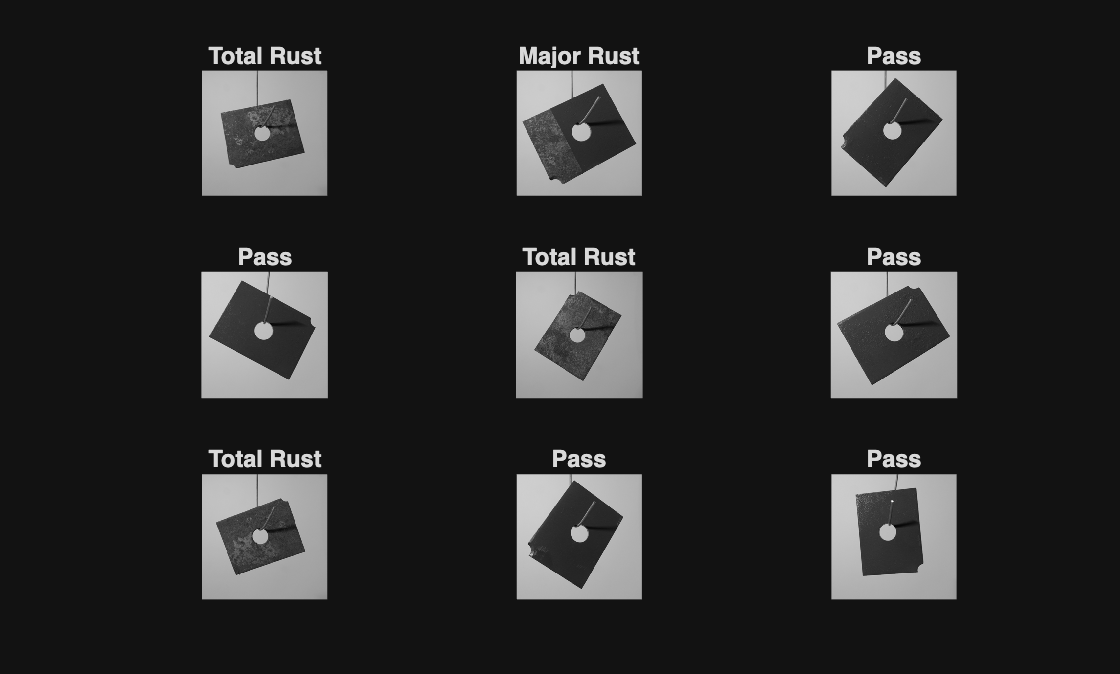

% Display a random sample of images to confirm standardization function
% works properly
idx = randperm(numImg,9);
for i = 1:9
    % Read random image from datastore
    img = readimage(partImgds,idx(i));
    
    % Apply standardization function to image
    img = standardizeImage(img);

    % Display image
    subplot(3,3,i)
    imshow(img)
    title(string(partImgds.Labels(idx(i))))
end



% Standardizes the image that is inputted to a standard size and grayscale
function img = standardizeImage(img)
    % Resize image to standard size
    img = imresize(img, [256, 256]);

    % Convert image from RGB to grayscale if needed
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
end


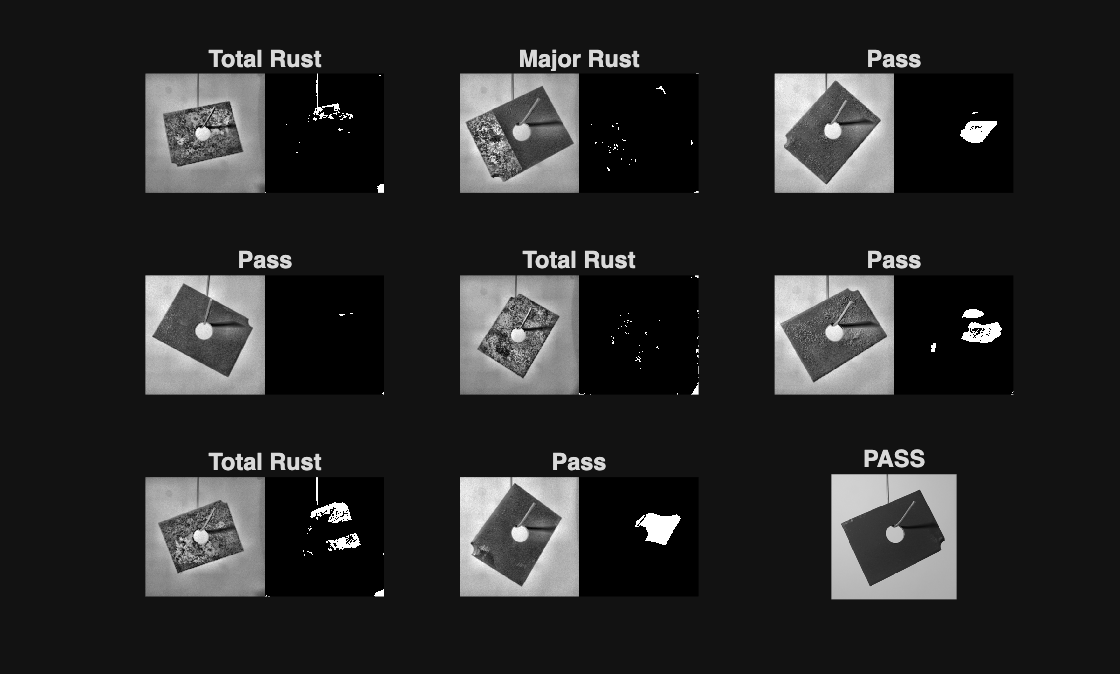

% Preprocessing

originalImg = readimage(partImgds, idx(2));
originalImg = standardizeImage(originalImg);

function img = preprocessImg(img)
% commented old code just in case
    % Turn unit8 into double (0,1) so pixel data is not lost during subtraction
    %img = im2double(img);

    % Remove uneven background lighting
    % img = imgaussfilt(img, 30);
    % img = img - background;

    % Rescale relatively to remove negative values created during
    % subtraction
    % img = mat2gray(img);


    

    % Apply smoothing to reduce some small image noise
    img = imgaussfilt(img, 0.5);

    % increase contrast, defects pop out better
    img = adapthisteq(img, "ClipLimit", 0.03, "Distribution", "rayleigh");

end

processedImg = preprocessImg(originalImg);
imshowpair(originalImg, processedImg, "montage");
% ROI and Segmentation

for n = 1:9 % for testing smaller datasets
    subplot(3,3,n)
    img1 = readimage(partImgds, idx(n));
    stdImg = standardizeImage(img1);
    processedImg = preprocessImg(stdImg);

    maskEvidence = defectEvidence(processedImg);

    imshowpair(processedImg,maskEvidence,"montage");
    title(string(partImgds.Labels(idx(n))))
end

function maskEvidence = defectEvidence(roi)
    
    % To separate the part from the background
    partMask = imbinarize(roi);
    partMask = ~partMask;
    imshow(partMask)

    % Neutralize the background
    maskedImg = roi;
    someValue = mean(maskedImg(partMask));
    maskedImg(imcomplement(partMask)) = someValue; % used imcomplement fcn to invert true output (white) to the defect

    % Smooth the pixels in the background
    smoothImg = imgaussfilt(maskedImg, 0.7);

    % Adaptive threshold 
    threshImg = adaptthresh(smoothImg,0.8);
    BW = imbinarize(threshImg);

    % Show only the defect inside the part
    BW = BW & partMask;
    
    % Identify and remove the hole in the plate from detection
    holeImg = regionprops(BW, 'Area', 'PixelIdxList');
    [maxArea,maxIndex] = max([holeImg.Area]); % finds the largest blob where the hole exists
    BW(holeImg(maxIndex).PixelIdxList) = false;
    
    maskEvidence = BW;
end

% Note: The hook in each image sometimes registers as false-positive
% evidence; the hole filtering has been tackled, but the hook has not

%Matthew Gonzalez - task 2.5

function metrics = quantifyDefects(maskEvidence, roi)
    
    cc = bwconncomp(maskEvidence); %find defect clusters
    numComponents = cc.NumObjects; %find amount of clusters
    
    props = regionprops(maskEvidence, 'Area'); %store the area of all clusters within array
    if isempty(props) %no clusters case
        maxArea = 0;
    else
        maxArea = max([props.Area]); %find defect/cluster with max area
end

areaRatio = nnz(maskEvidence) / numel(roi);
% find total pixels that are flagged as suspicious divided by
% total pixels in object to find the ratio of sus to not sus

metrics = struct(... %log metrics in structure
    'numComponents', numComponents, ...
    'maxArea', maxArea, ...
    'areaRatio', areaRatio ...
    );
end

% --- TEST RUN SCRIPT ---
% 1. Pick a random image from your datastore
testIdx = randperm(numImg, 1);
rawImg = readimage(partImgds, testIdx);
trueLabel = string(partImgds.Labels(testIdx));

% 2. Run through Standardization
stdImg = standardizeImage(rawImg);

% 3. Run through Preprocessing
processedImg = preprocessImg(stdImg);

% 4. Run through Defect Evidence & Segmentation
maskEvidence = defectEvidence(processedImg);

% 5. Run through Defect Quantification Metrics
metrics = quantifyDefects(maskEvidence, processedImg);

baselineDecision = decideRules(metrics); % for testing
imshow(stdImg);
title(baselineDecision);

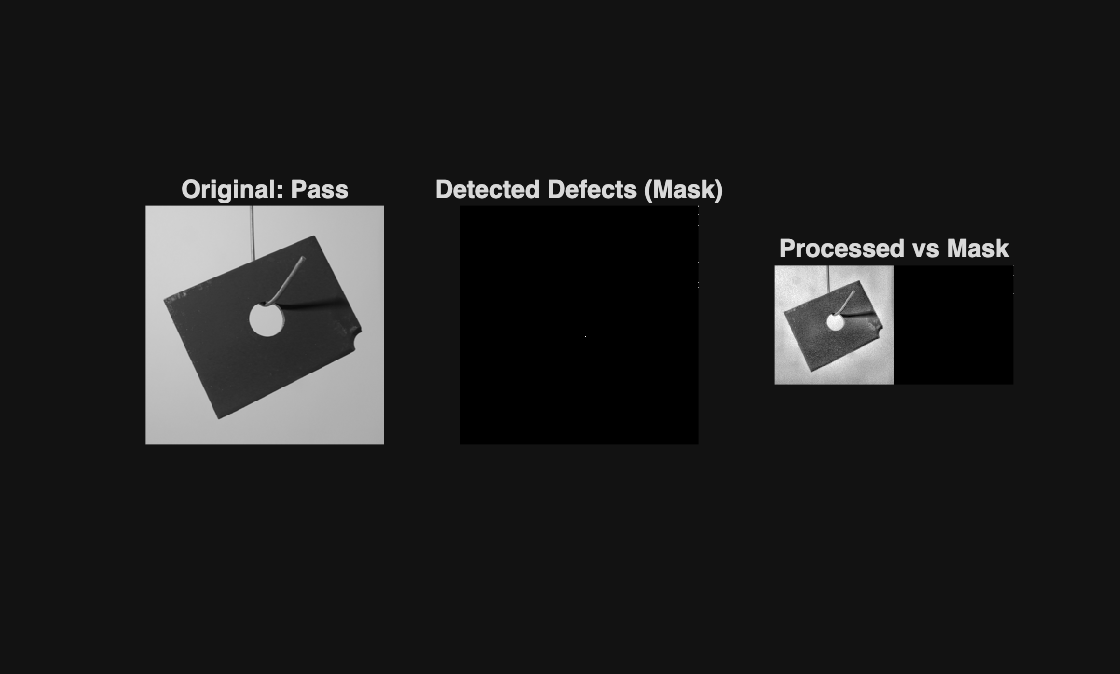


% 6. Display results for visual confirmation
figure;
subplot(1, 3, 1);
imshow(stdImg);
title(sprintf("Original: %s", trueLabel));

subplot(1, 3, 2);
imshow(maskEvidence);
title("Detected Defects (Mask)");

subplot(1, 3, 3);
imshowpair(processedImg, maskEvidence, "montage");
title("Processed vs Mask");


% 7. Print metrics to the Command Window to inspect them
disp("--- Computed Defect Metrics ---");

--- Computed Defect Metrics ---


disp(metrics);

    numComponents: 7
          maxArea: 1
        areaRatio: 1.0681e-04




% Fallback Decisions
function baselineDecision = decideRules(metrics)

    Amax = 5000; % High value because area data is unreliable
    Nmax = 50; % More accurate value compared to area so it makes the PASS/FAIL decision
    numComponents = metrics.numComponents;
    maxArea = metrics.maxArea;
    
    if maxArea > Amax || numComponents > Nmax
        baselineDecision = "FAIL";
    else 
        baselineDecision = "PASS";
    end
end

% NOTE: Baseline rule thresholds are approximate 
% Classical metrics have major overlap between PASS and FAIL w/ this
% dataset; can only serve as a conservative check rather than preciseness

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

Your goal in this step is to use a MathWorks provided pretrained network (recommended: `resnet18`) to classify each part as either a PASS or FAIL, that will be part of the output of the function you began to build in the previous step.

- Load the recommended starter network: use `imagePretrainedNetwork` and select `resnet18` from the Deep Learning Toolbox.

- Resize/augment input with `augmentedImageDatastore(...)` to match the network input size.

- Fine-tune the last layers for your classes (start with `PASS` vs `FAIL`), using `trainNetwork(...)` or a guided workflow such as [Get started with transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) or [pretrained network workflows](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html).

- The output of your AI classification model should be a predicted label (PASS/FAIL) and a confidence score in that label

Deliverable: `[aiLabel, aiScore] = classify(net, roiForNet)` 

% Create a new dataset with binary labels of Pass and Fail for the AI
% classifier
binaryLabels = partImgds.Labels;
binaryLabels(binaryLabels ~= "Pass") = "Fail";
binaryLabels = removecats(binaryLabels);
binaryImgds = imageDatastore(partImgds.Files);
binaryImgds.Labels = categorical(binaryLabels);

% Check number of images to confirm successful dataset creation
countEachLabel(binaryImgds)

ans = 2×2 table
    Label    Count
    _____    _____

    Pass      26  
    Fail      71  


% Split the dataset into a training set and testing set
[trainingImgds, testingImgds] = splitEachLabel(binaryImgds, 0.8, 'randomized');

% Check number of images in each set to confirm successful split, the
% training set should have about 80% of the images from the binary dataset
countEachLabel(trainingImgds)

ans = 2×2 table
    Label    Count
    _____    _____

    Pass      21  
    Fail      57  


countEachLabel(testingImgds)

ans = 2×2 table
    Label    Count
    _____    _____

    Pass       5  
    Fail      14  


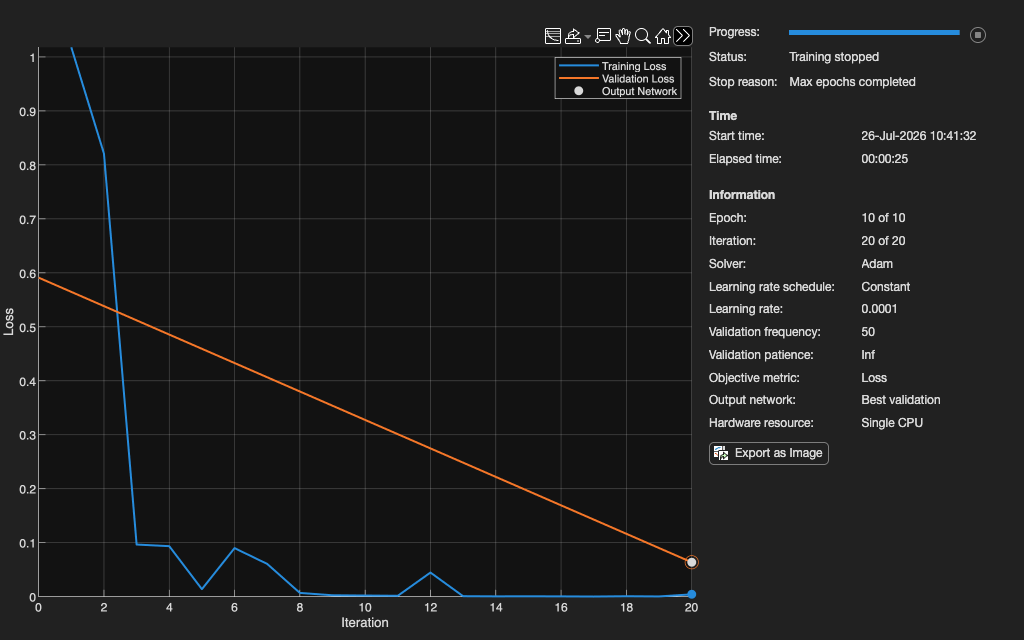

% Load ResNet-18 and get the input size
% NOTE: The add-on "Deep Learning Toolbox Model for ResNet-18 Network" must
% be installed for this model to work
net = imagePretrainedNetwork("resnet18", NumClasses = 2);
inputSize = net.Layers(1).InputSize;

% Create augmented image datasets for ResNet-18 to use
augmentedTrainingImgds = augmentedImageDatastore(inputSize(1:2), trainingImgds);
augmentedTestingImgds = augmentedImageDatastore(inputSize(1:2), testingImgds);

% Set up the options for training the model
options = trainingOptions("adam", InitialLearnRate = 0.0001, MaxEpochs = 10, MiniBatchSize = 32, ...
                          Shuffle = "every-epoch", ValidationData = augmentedTestingImgds, ...
                          Plots = "training-progress", Verbose = false);

% Train the model
net = trainnet(augmentedTrainingImgds, net, "crossentropy", options);

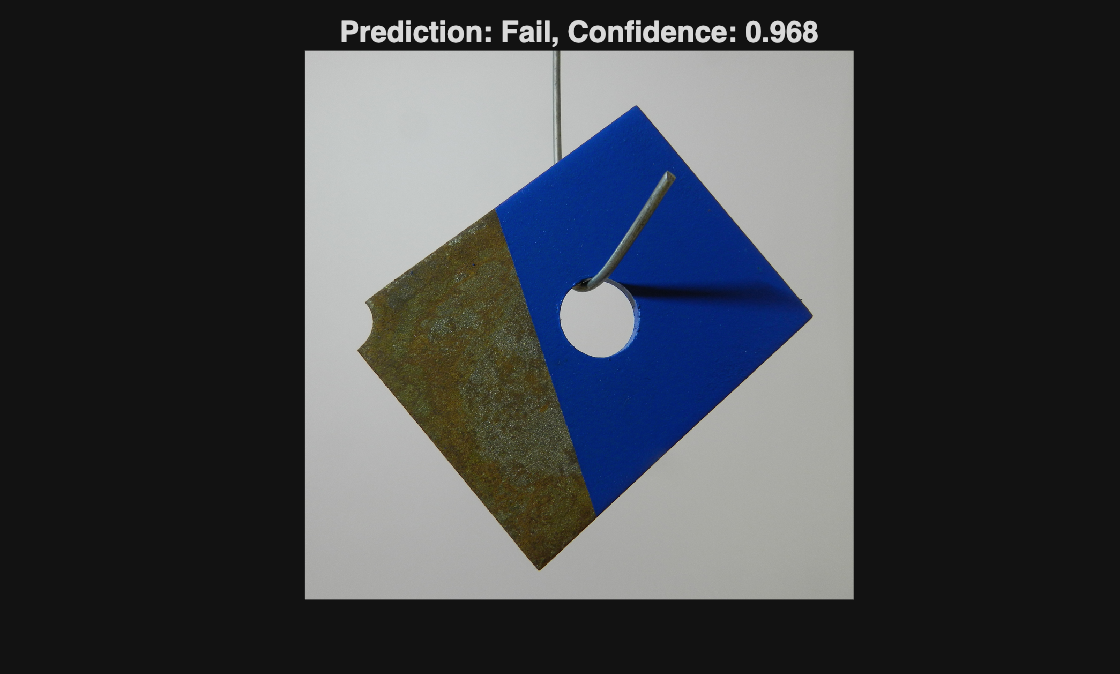

% Classification function, net is the trained AI model being used and
% roiForNet is the image being classified. The function will return Pass or
% Fail in aiLabel and the confidence percentage as a decimal (ex: 97% as
% 0.97) in aiScores
function [aiLabel, aiScores] = classify(net, roiForNet)
    % Change image specifications to ResNet-18's required specifications
    roiForNet = imresize(roiForNet, [244, 244]);
    if size(roiForNet, 3) == 1
        roiForNet = cat(3, roiForNet, roiForNet, roiForNet);
    end
    roiForNet = single(roiForNet);

    % Get the AI predictions for the chance of the image being a Pass and the
    % chance of the image being a Fail
    scores = predict(net, roiForNet);

    % The prediction with the highest percent is the returned prediction
    % along with the appropriate label
    [aiScores, index] = max(scores);
    classNames = ["Pass", "Fail"];
    aiLabel = classNames(index);
end

% Test classify function with a random image from the testing dataset
idx = randi(numel(testingImgds.Files));
testImg = readimage(testingImgds, idx);

[aiLabel, aiScore] = classify(net, testImg);
figure
imshow(testImg)
title("Prediction: " + string(aiLabel) + ", Confidence: " + string(round(aiScore, 3)))

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

Your image inspection function (e.g. `inspectPar(I)`) should combine the classical evidence with the AI classification output. 

In other words, your image inspection function should integrate both classical evidence from image processing and an AI classification decision. The AI classifier provides the main decision (PASS/FAIL) while the classical evidence extraction provides interpretability, traceability, and sanity checks for that decision.

Your function should return:

- `finalLabel` (from AI, in Task 3)

- `confidenceScore` (from AI, in Task 3)

- `evidenceOverlay` (from Step 4 in Task 2)

- `evidenceMetrics` (from Step 5 in Task 2)

- (optional) `baselineDecision` and a “disagreement flag” if optional rules in Step 6 from Task 2 and AI output disagree

Optionally, you can also choose to overlay these results on the image using `insertShape(...)` / `insertText(...)`, and save rejects with `imwrite(...)`

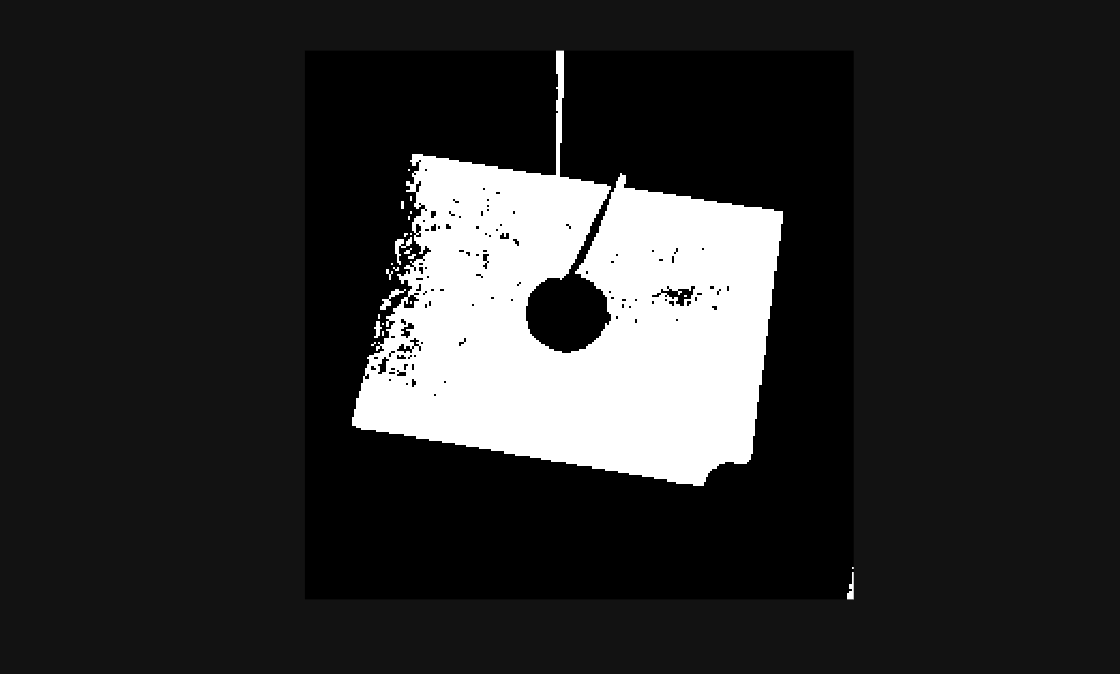

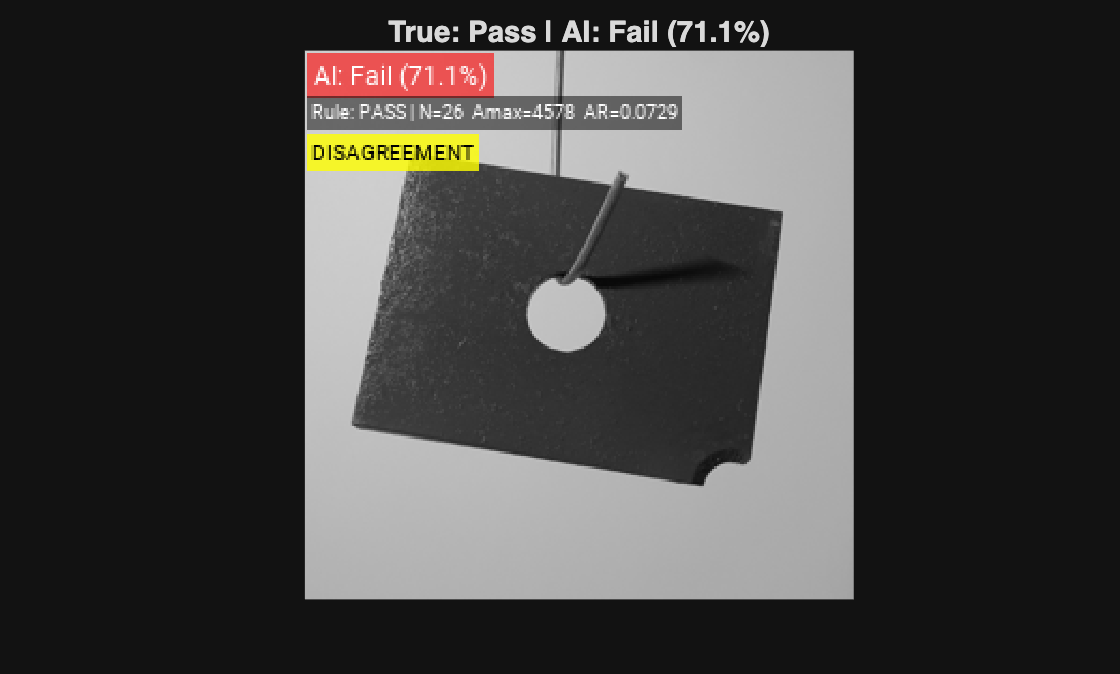

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision] = inspectPart(I)

    % You can write your function here 
end

## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.





## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?